### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')


### Calculate oxygen sensor lag for CTD alignment 

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year5')

% Casts 
cast01 = readSBScnv( 'ar30-03001_hyst.cnv' );
cast02 = readSBScnv( 'ar30-03002_hyst.cnv' );
cast02b = readSBScnv( 'ar30-03002b_hyst.cnv' );
cast03 = readSBScnv( 'ar30-03003_hyst.cnv' );
cast04 = readSBScnv( 'ar30-03004_hyst.cnv' );
cast05 = readSBScnv( 'ar30-03005_hyst.cnv' );
cast06 = readSBScnv( 'ar30-03006_hyst.cnv' );
cast07 = readSBScnv( 'ar30-03007_hyst.cnv' );
cast08 = readSBScnv( 'ar30-03008_hyst.cnv' );
cast09 = readSBScnv( 'ar30-03009_hyst.cnv' );
cast10 = readSBScnv( 'ar30-03010_hyst.cnv' );
cast11 = readSBScnv( 'ar30-03011_hyst.cnv' );
cast12 = readSBScnv( 'ar30-03012_hyst.cnv' );
cast13 = readSBScnv( 'ar30-03013_hyst.cnv' );
cast14 = readSBScnv( 'ar30-03014_hyst.cnv' );
cast15 = readSBScnv( 'ar30-03015_hyst.cnv' );
cast16 = readSBScnv( 'ar30-03016_hyst.cnv' );
cast17 = readSBScnv( 'ar30-03017_hyst.cnv' );
cast18 = readSBScnv( 'ar30-03018_hyst.cnv' );
cast19 = readSBScnv( 'ar30-03019_hyst.cnv' );
cast20 = readSBScnv( 'ar30-03020_hyst.cnv' );
cast21 = readSBScnv( 'ar30-03021_hyst.cnv' );
cast22 = readSBScnv( 'ar30-03022_hyst.cnv' );
cast23 = readSBScnv( 'ar30-03023_hyst.cnv' );

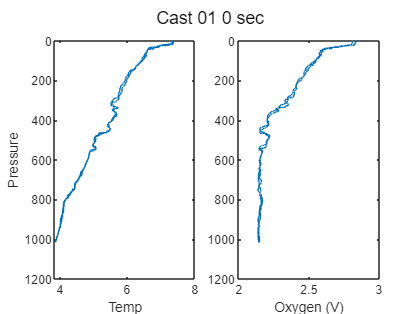

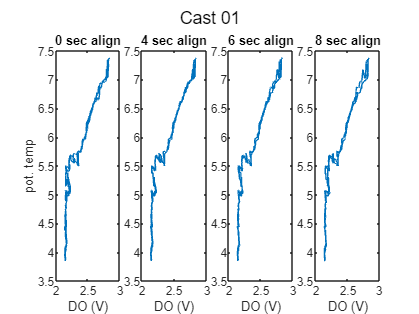

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
cast01 = align_CTD_KF(cast01,'Cast 01',a1,a2,a3);

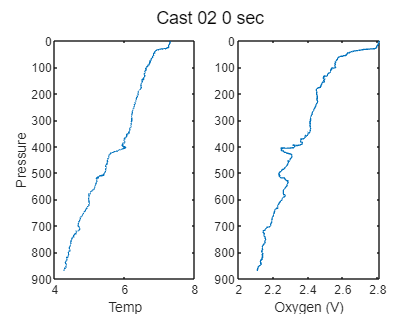

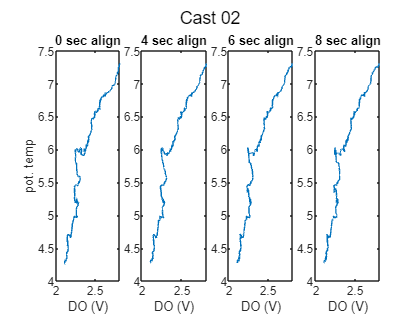

cast02 = align_CTD_KF(cast02,'Cast 02',a1,a2,a3);

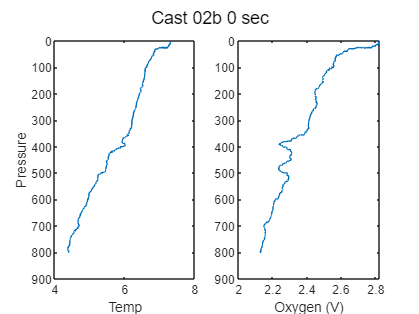

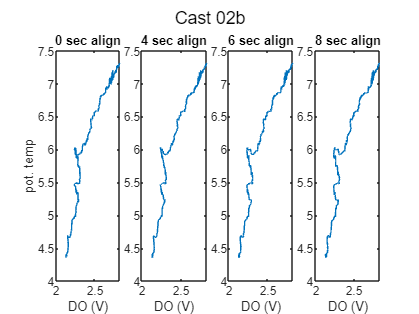

cast02b = align_CTD_KF(cast02b,'Cast 02b',a1,a2,a3);

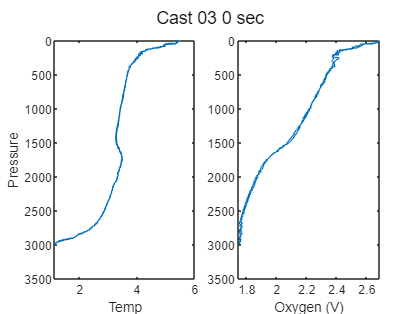

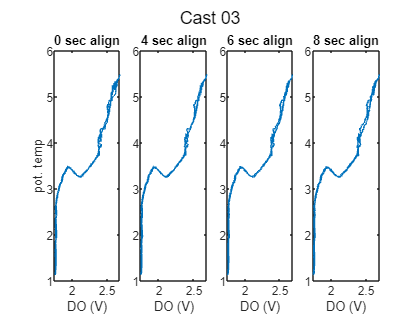

cast03 = align_CTD_KF(cast03,'Cast 03',a1,a2,a3);

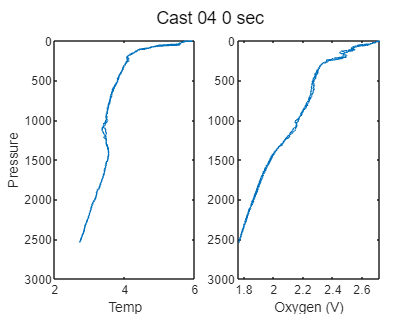

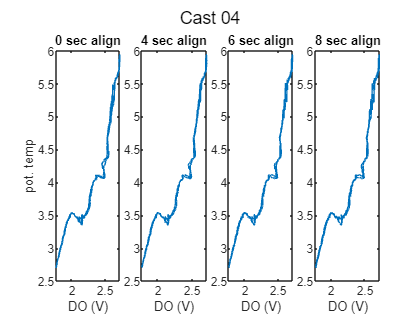

cast04 = align_CTD_KF(cast04,'Cast 04',a1,a2,a3);

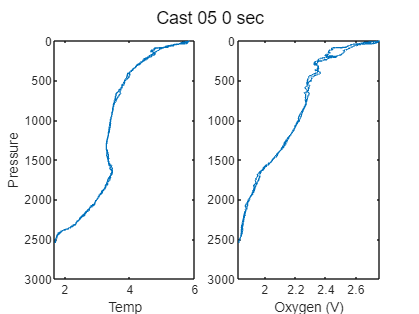

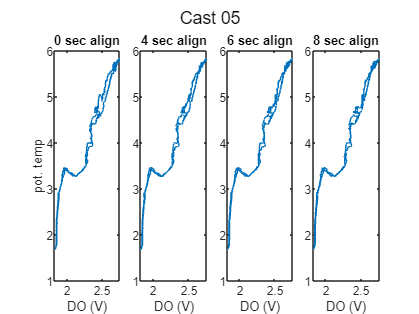

cast05 = align_CTD_KF(cast05,'Cast 05',a1,a2,a3);

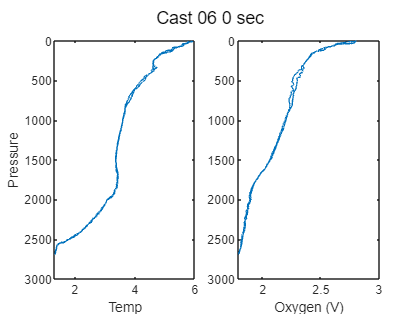

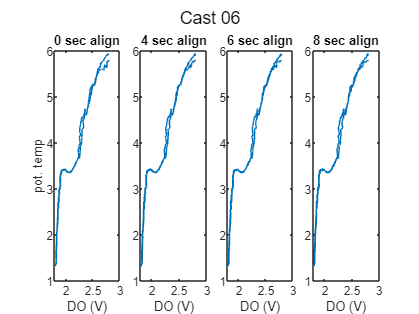

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

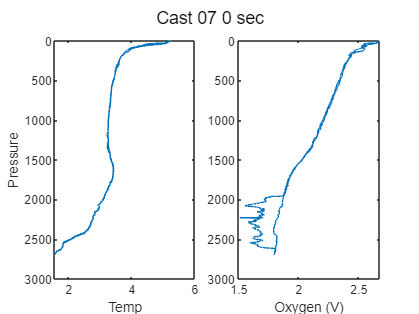

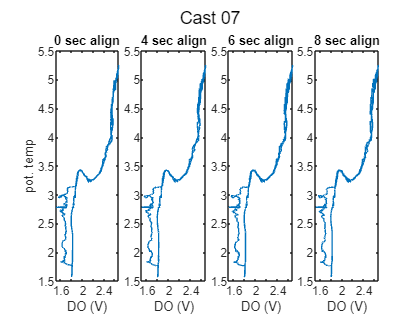

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

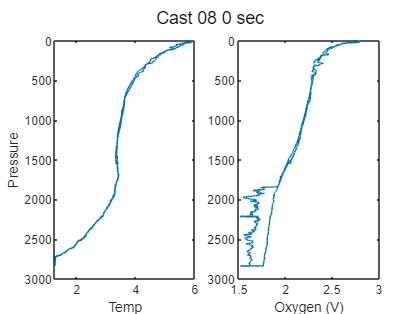

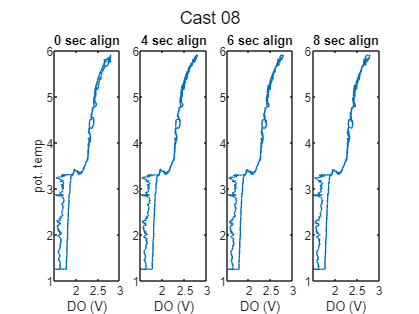

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

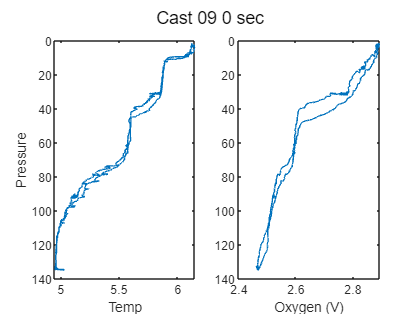

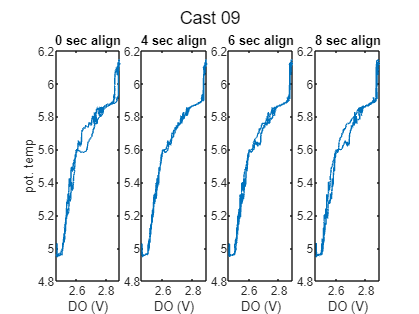

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

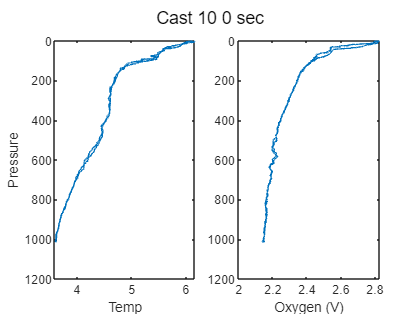

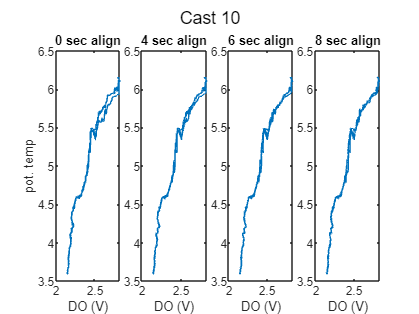

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);

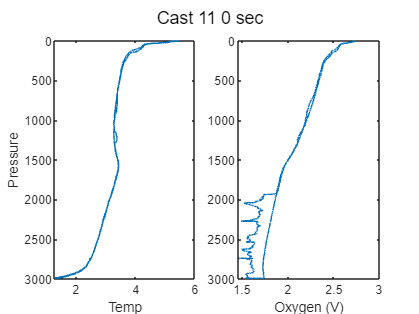

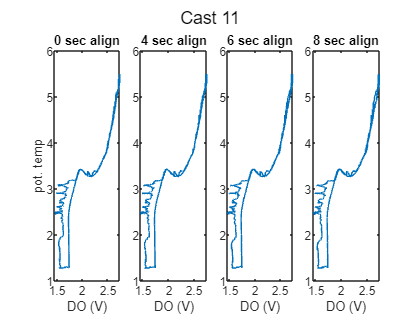

cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);

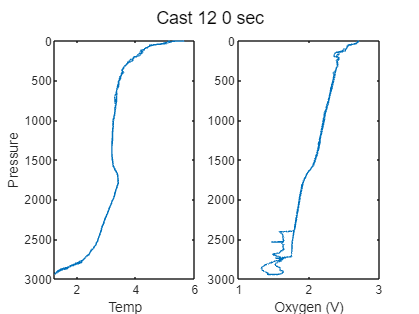

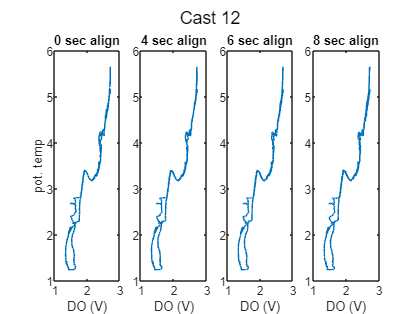

cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);

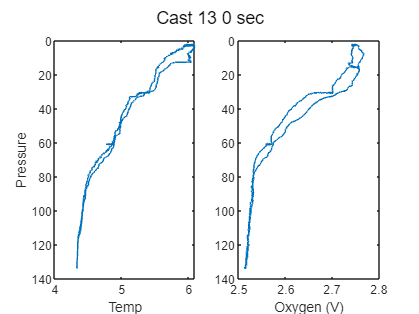

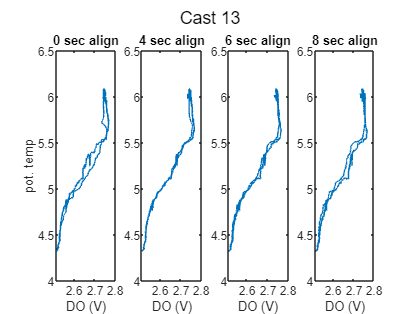

cast13 = align_CTD_KF(cast13,'Cast 13',a1,a2,a3);

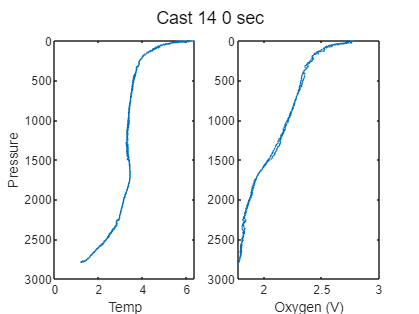

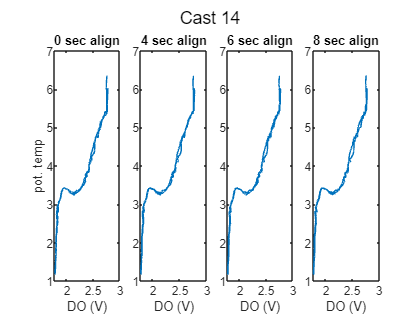

cast14 = align_CTD_KF(cast14,'Cast 14',a1,a2,a3);

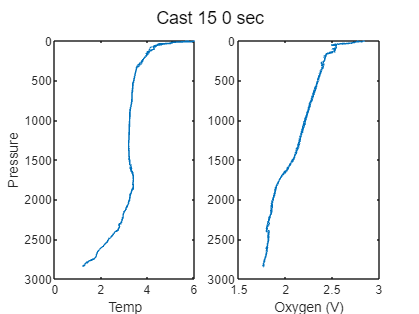

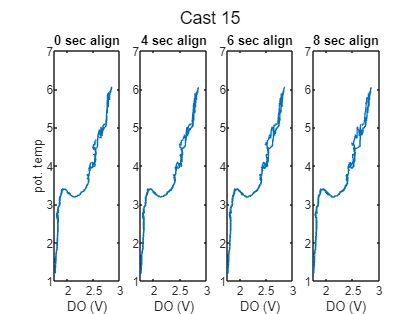

cast15 = align_CTD_KF(cast15,'Cast 15',a1,a2,a3);

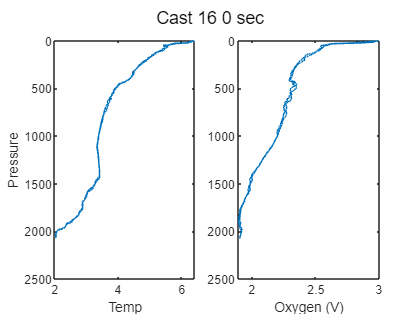

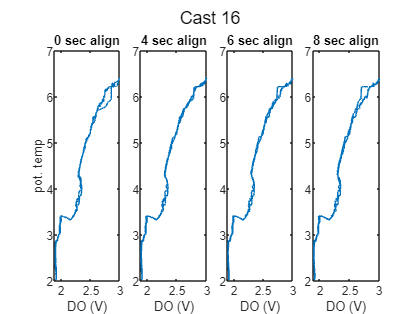

cast16 = align_CTD_KF(cast16,'Cast 16',a1,a2,a3);

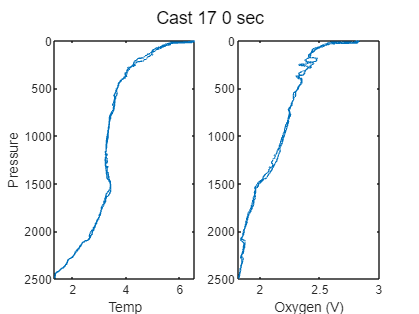

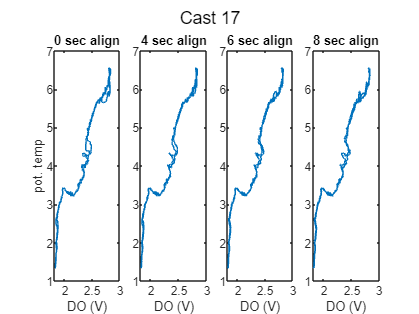

cast17 = align_CTD_KF(cast17,'Cast 17',a1,a2,a3);

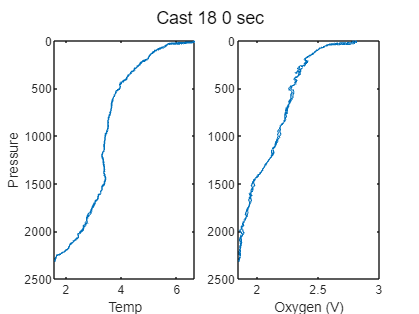

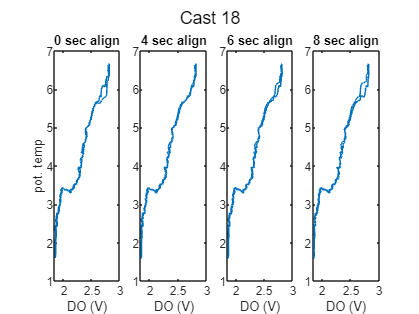

cast18 = align_CTD_KF(cast18,'Cast 18',a1,a2,a3);

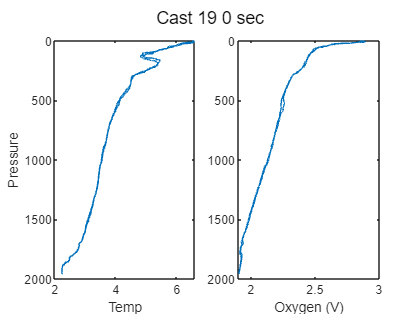

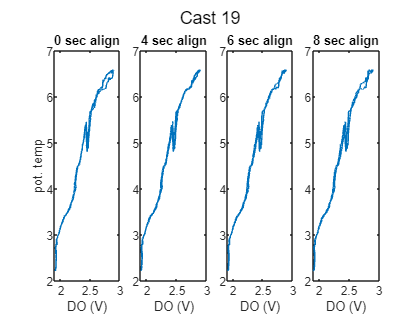

cast19 = align_CTD_KF(cast19,'Cast 19',a1,a2,a3);

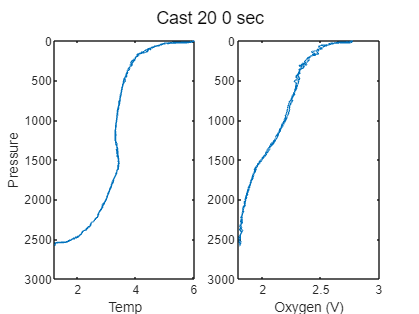

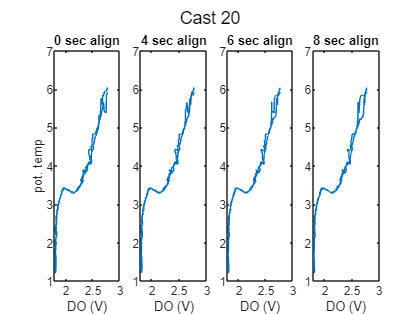

cast20 = align_CTD_KF(cast20,'Cast 20',a1,a2,a3);

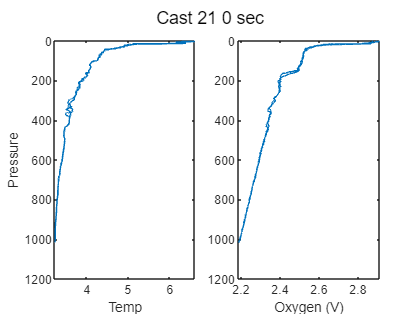

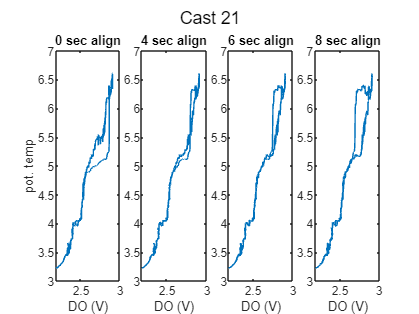

cast21 = align_CTD_KF(cast21,'Cast 21',a1,a2,a3);

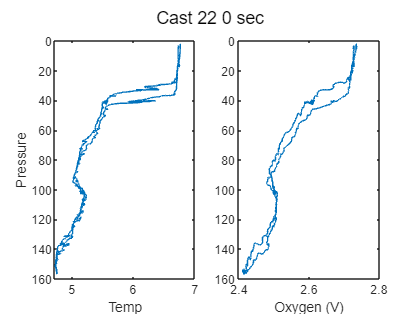

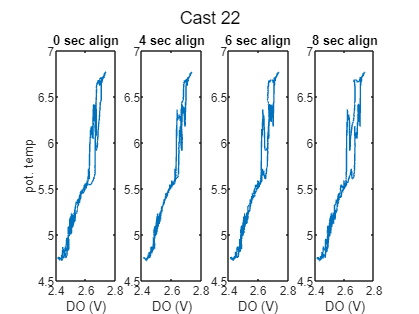

cast22 = align_CTD_KF(cast22,'Cast 22',a1,a2,a3);

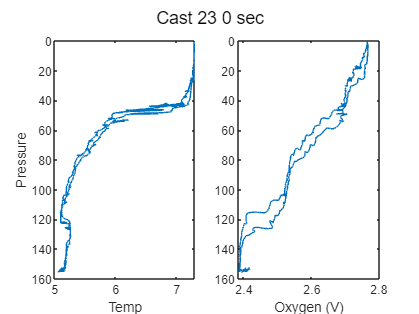

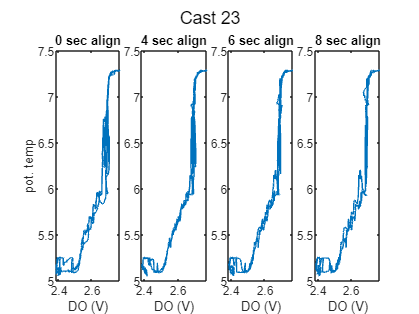

cast23 = align_CTD_KF(cast23,'Cast 23',a1,a2,a3);

% Pick align_sec

a1 = 4;
align_sec = a1; 
clear cast*

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

CTD_sen = 2; % Use primary or secondary CTD temp and sal

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year5')
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year5\Final_From_Leah')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year5')

btl = readtable('Irminger_Sea-05_AR30-03_Combo_Winklers_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum15 = btl(btl.Cast == 15,:);
btlsum21 = btl(btl.Cast == 21,:);

% [btlsum] = combine_btl_files(leah_btl_file,btl_file,btlsum,CTD_sen)
btlsum05 = combine_btl_files('ar30-03_005.cbot_s','ar30-03005.csv',btlsum05,CTD_sen);

btlsum06 = combine_btl_files('ar30-03_006.cbot_s','ar30-03006.csv',btlsum06,CTD_sen);

btlsum07 = combine_btl_files('ar30-03_007.cbot_s','ar30-03007.csv',btlsum07,CTD_sen);

btlsum10 = combine_btl_files('ar30-03_010.cbot_s','ar30-03010.csv',btlsum10,CTD_sen);

btlsum15 = combine_btl_files('ar30-03_015.cbot_s','ar30-03015.csv',btlsum15,CTD_sen);

btlsum21 = combine_btl_files('ar30-03_021.cbot_s','ar30-03021.csv',btlsum21,CTD_sen);


btlsum0 = [btlsum05; btlsum06; btlsum07; btlsum15]; % casts that are being processed for E2 and gain together 

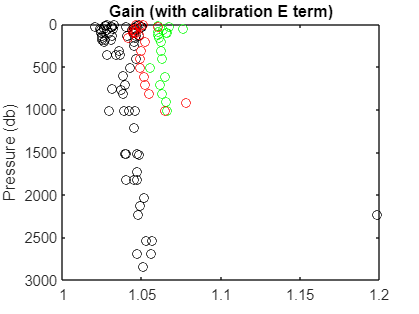

figure % Uses oxygen (ml/l) recalculated using Leah's finalized salinity product 
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal,btlsum0.PrDM,'ok')
hold on
plot(btlsum10.Winkler_mLL./btlsum10.CTDoxy_mLL_hyst,btlsum10.PrDM,'go')
plot(btlsum21.Winkler_mLL./btlsum21.CTDoxy_mLL_hyst,btlsum21.PrDM,'ro')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

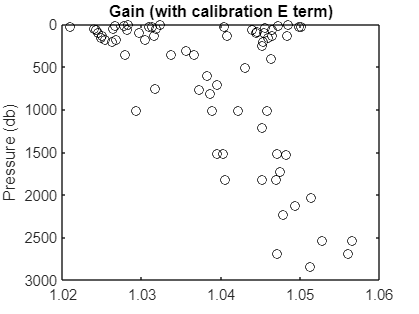


gain0_threshold_high = 1.12;
gain0 = btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal;
Wink_high = find(gain0 > gain0_threshold_high);
btlsum0.Winkler_mLL(Wink_high) = NaN;

figure
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

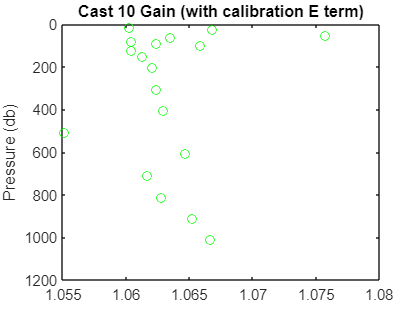


figure
plot(btlsum10.Winkler_mLL./btlsum10.CTDoxy_mLL_cal,btlsum10.PrDM,'og')
axis ij
ylabel('Pressure (db)')
title('Cast 10 Gain (with calibration E term)')

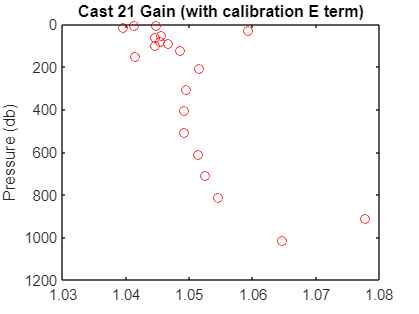


figure
plot(btlsum21.Winkler_mLL./btlsum21.CTDoxy_mLL_cal,btlsum21.PrDM,'or')
axis ij
ylabel('Pressure (db)')
title('Cast 21 Gain (with calibration E term)')

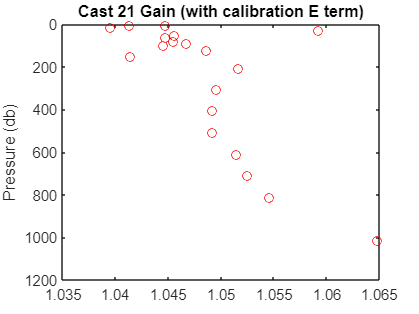


gain0_threshold_high = 1.07;
gain0 = btlsum21.Winkler_mLL./btlsum21.CTDoxy_mLL_cal;
Wink_high = find(gain0 > gain0_threshold_high);
btlsum21.Winkler_mLL(Wink_high) = NaN;

figure
plot(btlsum21.Winkler_mLL./btlsum21.CTDoxy_mLL_cal,btlsum21.PrDM,'or')
axis ij
ylabel('Pressure (db)')
title('Cast 21 Gain (with calibration E term)')

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.61460e-001);
cal.VOFFSET = double(-5.04500e-001);
cal.A = double(-3.49610e-003);
cal.B = double(1.57460e-004);
cal.C = double(-2.32160e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.00000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '0113';
cal.OCALDATE = '09-May-17';

H = [-0.033, 5000, 1450]; % Default 

cal10 = cal; % To calc gain and SOC for just cast 10
cal21 = cal; % To calc gain and SOC for just cast 21 

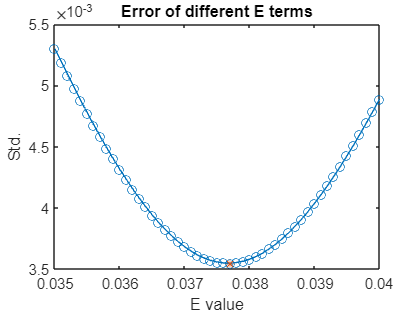

cal.E2 = 0.0377


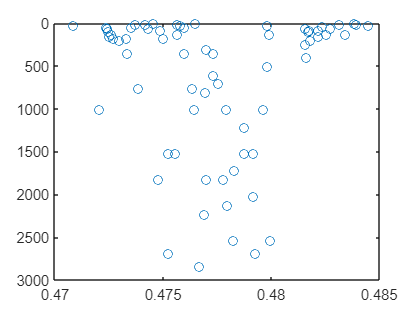

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing') 
[cal] = E2_calculation(btlsum0,cal,CTD_sen); % Use dummy bottle summary with outlier removed

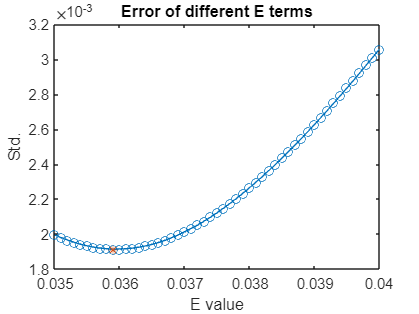

cal.E2 = 0.0359


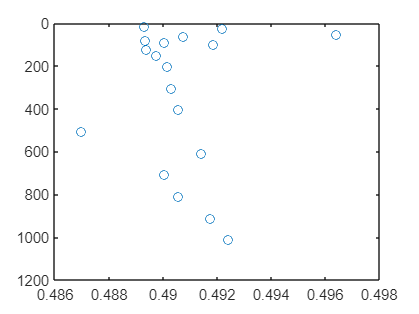

[cal10] = E2_calculation(btlsum10,cal10,CTD_sen); % Different calc for Cast 10

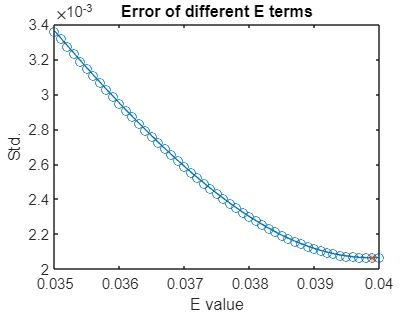

cal.E2 = 0.0399


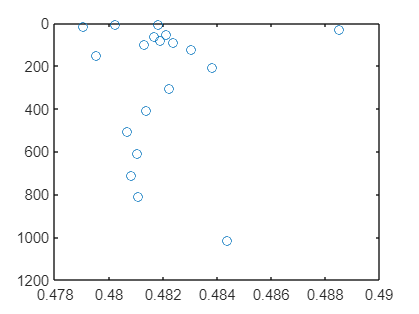

[cal21] = E2_calculation(btlsum21,cal21,CTD_sen); % Different calc for Cast 21

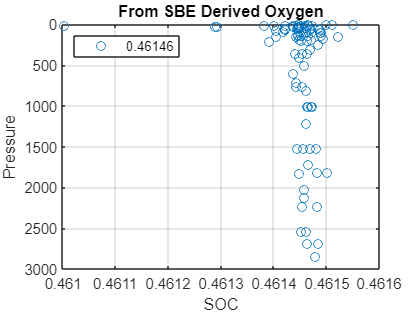

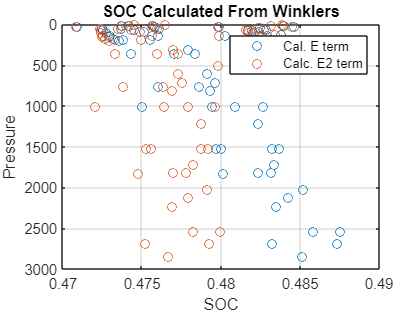

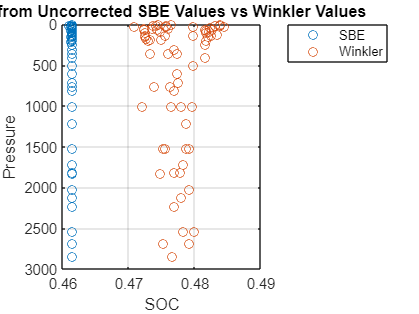

New SOC = 0.47748
EGain = 1.0347+/- 0.0076861



[cal] = Gain_E2_Calculation(btlsum0,cal,CTD_sen); % Use dummy bottle summary with any outliers removed

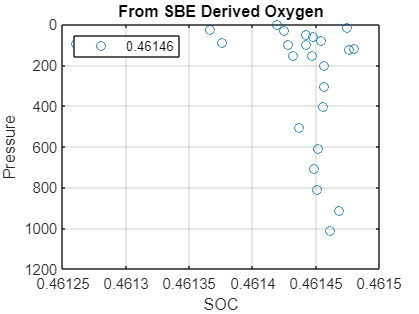

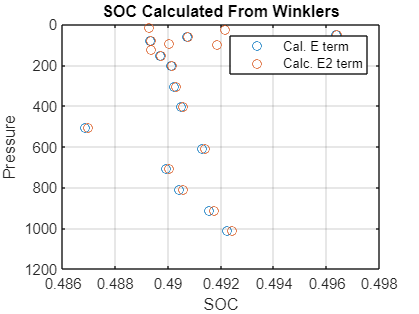

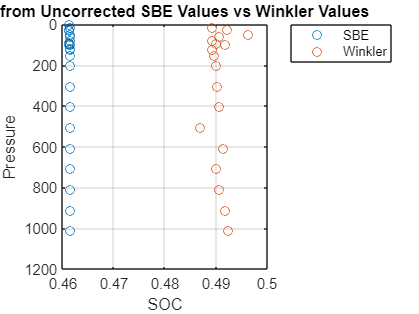

New SOC = 0.49074
EGain = 1.0634+/- 0.0041457


[cal10] = Gain_E2_Calculation(btlsum10,cal10,CTD_sen); % Cast 10, with new E2 term

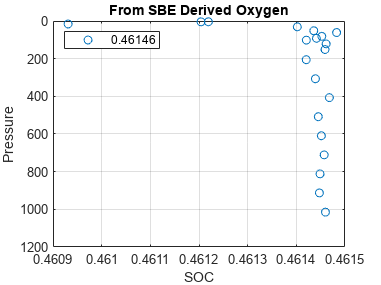

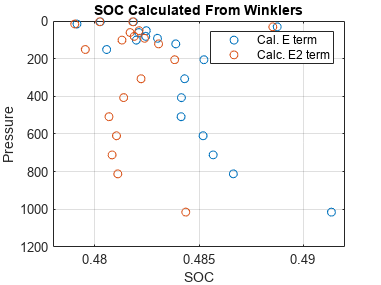

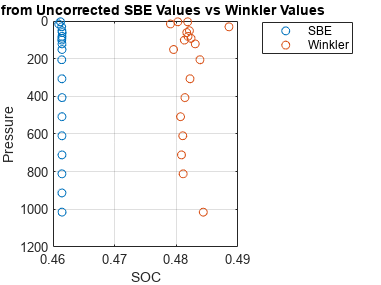

New SOC = 0.48195
EGain = 1.0444+/- 0.0044719


[cal21] = Gain_E2_Calculation(btlsum21,cal21,CTD_sen); % Cast 21, with new E2 term 

### Combine Leah's processed cast files with my processed cast files 

% Read in processed casts
% Processed with 4 sec DO alignment and SBE default hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year5')
% Casts 
cast01u = readSBScnv( 'uar30-03001.cnv' );
cast02u = readSBScnv( 'uar30-03002.cnv' );
cast02bu = readSBScnv( 'uar30-03002b.cnv' );
cast03u = readSBScnv( 'uar30-03003.cnv' );
cast04u = readSBScnv( 'uar30-03004.cnv' );
cast05u = readSBScnv( 'uar30-03005.cnv' );
cast06u = readSBScnv( 'uar30-03006.cnv' );
cast07u = readSBScnv( 'uar30-03007.cnv' );
cast08u = readSBScnv( 'uar30-03008.cnv' );
cast09u = readSBScnv( 'uar30-03009.cnv' );
cast10u = readSBScnv( 'uar30-03010.cnv' );
cast11u = readSBScnv( 'uar30-03011.cnv' );
cast12u = readSBScnv( 'uar30-03012.cnv' );
cast13u = readSBScnv( 'uar30-03013.cnv' );
cast14u = readSBScnv( 'uar30-03014.cnv' );
cast15u = readSBScnv( 'uar30-03015.cnv' );
cast16u = readSBScnv( 'uar30-03016.cnv' );
cast17u = readSBScnv( 'uar30-03017.cnv' );
cast18u = readSBScnv( 'uar30-03018.cnv' );
cast19u = readSBScnv( 'uar30-03019.cnv' );
cast20u = readSBScnv( 'uar30-03020.cnv' );
cast21u = readSBScnv( 'uar30-03021.cnv' );
cast22u = readSBScnv( 'uar30-03022.cnv' );
cast23u = readSBScnv( 'uar30-03023.cnv' );

cast01d = readSBScnv( 'dar30-03001.cnv' );
cast02d = readSBScnv( 'dar30-03002.cnv' );
cast02bd = readSBScnv( 'dar30-03002b.cnv' );
cast03d = readSBScnv( 'dar30-03003.cnv' );
cast04d = readSBScnv( 'dar30-03004.cnv' );
cast05d = readSBScnv( 'dar30-03005.cnv' );
cast06d = readSBScnv( 'dar30-03006.cnv' );
cast07d = readSBScnv( 'dar30-03007.cnv' );
cast08d = readSBScnv( 'dar30-03008.cnv' );
cast09d = readSBScnv( 'dar30-03009.cnv' );
cast10d = readSBScnv( 'dar30-03010.cnv' );
cast11d = readSBScnv( 'dar30-03011.cnv' );
cast12d = readSBScnv( 'dar30-03012.cnv' );
cast13d = readSBScnv( 'dar30-03013.cnv' );
cast14d = readSBScnv( 'dar30-03014.cnv' );
cast15d = readSBScnv( 'dar30-03015.cnv' );
cast16d = readSBScnv( 'dar30-03016.cnv' );
cast17d = readSBScnv( 'dar30-03017.cnv' );
cast18d = readSBScnv( 'dar30-03018.cnv' );
cast19d = readSBScnv( 'dar30-03019.cnv' );
cast20d = readSBScnv( 'dar30-03020.cnv' );
cast21d = readSBScnv( 'dar30-03021.cnv' );
cast22d = readSBScnv( 'dar30-03022.cnv' );
cast23d = readSBScnv( 'dar30-03023.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year5\Final_From_Leah')
load ar30-03_final.mat

% Combine leah's finalized product with my oxygen file 
% function [cast,cast0] = combine_CTD_files(leah_cast,cast,CTD_sen)

% [cast01u, cast01u0] = combine_CTD_files(ar30_001u,cast01u,CTD_sen); [cast01d, cast01d0] = combine_CTD_files(ar30_001d,cast01d,CTD_sen);  
% % [cast02u, cast02u0] = combine_CTD_files(ar30_002u,cast02bu,CTD_sen); [cast02d, cast02d0] = combine_CTD_files(ar30_002d,cast02bd,CTD_sen);  
% [cast03u, cast03u0] = combine_CTD_files(ar30_003u,cast03u,CTD_sen); [cast03d, cast03d0] = combine_CTD_files(ar30_003d,cast03d,CTD_sen);  
% [cast04u, cast04u0] = combine_CTD_files(ar30_004u,cast04u,CTD_sen); [cast04d, cast04d0] = combine_CTD_files(ar30_004d,cast04d,CTD_sen);  
% [cast05u, cast05u0] = combine_CTD_files(ar30_005u,cast05u,CTD_sen); [cast05d, cast05d0] = combine_CTD_files(ar30_005d,cast05d,CTD_sen);  
% [cast06u, cast06u0] = combine_CTD_files(ar30_006u,cast06u,CTD_sen); [cast06d, cast06d0] = combine_CTD_files(ar30_006d,cast06d,CTD_sen);  
% [cast07u, cast07u0] = combine_CTD_files(ar30_007u,cast07u,CTD_sen); [cast07d, cast07d0] = combine_CTD_files(ar30_007d,cast07d,CTD_sen);  
% [cast08u, cast08u0] = combine_CTD_files(ar30_008u,cast08u,CTD_sen); [cast08d, cast08d0] = combine_CTD_files(ar30_008d,cast08d,CTD_sen);  
% [cast09u, cast09u0] = combine_CTD_files(ar30_009u,cast09u,CTD_sen); [cast09d, cast09d0] = combine_CTD_files(ar30_009d,cast09d,CTD_sen);  
% [cast10u, cast10u0] = combine_CTD_files(ar30_010u,cast10u,CTD_sen); [cast10d, cast10d0] = combine_CTD_files(ar30_010d,cast10d,CTD_sen);  
% [cast11u, cast11u0] = combine_CTD_files(ar30_011u,cast11u,CTD_sen); [cast11d, cast11d0] = combine_CTD_files(ar30_011d,cast11d,CTD_sen);  
% [cast12u, cast12u0] = combine_CTD_files(ar30_012u,cast12u,CTD_sen); [cast12d, cast12d0] = combine_CTD_files(ar30_012d,cast12d,CTD_sen);  
% [cast13u, cast13u0] = combine_CTD_files(ar30_013u,cast13u,CTD_sen); [cast13d, cast13d0] = combine_CTD_files(ar30_013d,cast13d,CTD_sen);  
% [cast14u, cast14u0] = combine_CTD_files(ar30_014u,cast14u,CTD_sen); [cast14d, cast14d0] = combine_CTD_files(ar30_014d,cast14d,CTD_sen);  
% [cast15u, cast15u0] = combine_CTD_files(ar30_015u,cast15u,CTD_sen); [cast15d, cast15d0] = combine_CTD_files(ar30_015d,cast15d,CTD_sen);  
% [cast16u, cast16u0] = combine_CTD_files(ar30_016u,cast16u,CTD_sen); [cast16d, cast16d0] = combine_CTD_files(ar30_016d,cast16d,CTD_sen);  
% [cast17u, cast17u0] = combine_CTD_files(ar30_017u,cast17u,CTD_sen); [cast17d, cast17d0] = combine_CTD_files(ar30_017d,cast17d,CTD_sen);  
% [cast18u, cast18u0] = combine_CTD_files(ar30_018u,cast18u,CTD_sen); [cast18d, cast18d0] = combine_CTD_files(ar30_018d,cast18d,CTD_sen);  
% [cast19u, cast19u0] = combine_CTD_files(ar30_019u,cast19u,CTD_sen); [cast19d, cast19d0] = combine_CTD_files(ar30_019d,cast19d,CTD_sen);  
% [cast20u, cast20u0] = combine_CTD_files(ar30_020u,cast20u,CTD_sen); [cast20d, cast20d0] = combine_CTD_files(ar30_020d,cast20d,CTD_sen);  
% [cast21u, cast21u0] = combine_CTD_files(ar30_021u,cast21u,CTD_sen); [cast21d, cast21d0] = combine_CTD_files(ar30_021d,cast21d,CTD_sen);  
% [cast22u, cast22u0] = combine_CTD_files(ar30_022u,cast22u,CTD_sen); [cast22d, cast22d0] = combine_CTD_files(ar30_022d,cast22d,CTD_sen);  
% [cast23u, cast23u0] = combine_CTD_files(ar30_023u,cast23u,CTD_sen); [cast23d, cast23d0] = combine_CTD_files(ar30_023d,cast23d,CTD_sen);  


[cast01u, ~] = combine_CTD_files(ar30_001u,cast01u,CTD_sen); [cast01d, ~] = combine_CTD_files(ar30_001d,cast01d,CTD_sen);  
% [cast02u, ~] = combine_CTD_files(ar30_002u,cast02bu,CTD_sen); [cast02d, ~] = combine_CTD_files(ar30_002d,cast02bd,CTD_sen);  
[cast03u, ~] = combine_CTD_files(ar30_003u,cast03u,CTD_sen); [cast03d, ~] = combine_CTD_files(ar30_003d,cast03d,CTD_sen);  
[cast04u, ~] = combine_CTD_files(ar30_004u,cast04u,CTD_sen); [cast04d, ~] = combine_CTD_files(ar30_004d,cast04d,CTD_sen);  
[cast05u, ~] = combine_CTD_files(ar30_005u,cast05u,CTD_sen); [cast05d, ~] = combine_CTD_files(ar30_005d,cast05d,CTD_sen);  
[cast06u, ~] = combine_CTD_files(ar30_006u,cast06u,CTD_sen); [cast06d, ~] = combine_CTD_files(ar30_006d,cast06d,CTD_sen);  
[cast07u, ~] = combine_CTD_files(ar30_007u,cast07u,CTD_sen); [cast07d, ~] = combine_CTD_files(ar30_007d,cast07d,CTD_sen);  
[cast08u, ~] = combine_CTD_files(ar30_008u,cast08u,CTD_sen); [cast08d, ~] = combine_CTD_files(ar30_008d,cast08d,CTD_sen);  
[cast09u, ~] = combine_CTD_files(ar30_009u,cast09u,CTD_sen); [cast09d, ~] = combine_CTD_files(ar30_009d,cast09d,CTD_sen);  
[cast10u, ~] = combine_CTD_files(ar30_010u,cast10u,CTD_sen); [cast10d, ~] = combine_CTD_files(ar30_010d,cast10d,CTD_sen);  
[cast11u, ~] = combine_CTD_files(ar30_011u,cast11u,CTD_sen); [cast11d, ~] = combine_CTD_files(ar30_011d,cast11d,CTD_sen);  
[cast12u, ~] = combine_CTD_files(ar30_012u,cast12u,CTD_sen); [cast12d, ~] = combine_CTD_files(ar30_012d,cast12d,CTD_sen);  
[cast13u, ~] = combine_CTD_files(ar30_013u,cast13u,CTD_sen); [cast13d, ~] = combine_CTD_files(ar30_013d,cast13d,CTD_sen);  
[cast14u, ~] = combine_CTD_files(ar30_014u,cast14u,CTD_sen); [cast14d, ~] = combine_CTD_files(ar30_014d,cast14d,CTD_sen);  
[cast15u, ~] = combine_CTD_files(ar30_015u,cast15u,CTD_sen); [cast15d, ~] = combine_CTD_files(ar30_015d,cast15d,CTD_sen);  
[cast16u, ~] = combine_CTD_files(ar30_016u,cast16u,CTD_sen); [cast16d, ~] = combine_CTD_files(ar30_016d,cast16d,CTD_sen);  
[cast17u, ~] = combine_CTD_files(ar30_017u,cast17u,CTD_sen); [cast17d, ~] = combine_CTD_files(ar30_017d,cast17d,CTD_sen);  
[cast18u, ~] = combine_CTD_files(ar30_018u,cast18u,CTD_sen); [cast18d, ~] = combine_CTD_files(ar30_018d,cast18d,CTD_sen);  
[cast19u, ~] = combine_CTD_files(ar30_019u,cast19u,CTD_sen); [cast19d, ~] = combine_CTD_files(ar30_019d,cast19d,CTD_sen);  
[cast20u, ~] = combine_CTD_files(ar30_020u,cast20u,CTD_sen); [cast20d, ~] = combine_CTD_files(ar30_020d,cast20d,CTD_sen);  
[cast21u, ~] = combine_CTD_files(ar30_021u,cast21u,CTD_sen); [cast21d, ~] = combine_CTD_files(ar30_021d,cast21d,CTD_sen);  
[cast22u, ~] = combine_CTD_files(ar30_022u,cast22u,CTD_sen); [cast22d, ~] = combine_CTD_files(ar30_022d,cast22d,CTD_sen);  
[cast23u, ~] = combine_CTD_files(ar30_023u,cast23u,CTD_sen); [cast23d, ~] = combine_CTD_files(ar30_023d,cast23d,CTD_sen);  

### Correct casts using new SOC term, E term, and Leah's calibrated salinity product

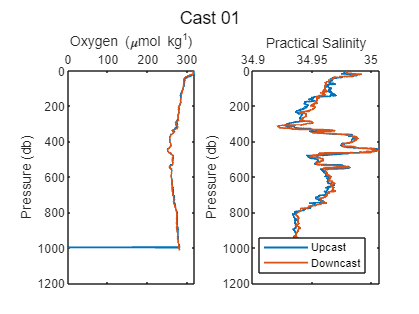

sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_v2(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)
[cast01u, cast01d, btlsum01] = Process_Cast_Gain_E2_v2(cast01u,cast01d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 01');

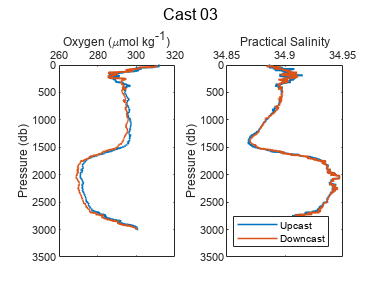

% [cast02bu, cast02bd, btlsum02b] = Process_Cast_Gain_E2(cast02bu,cast02bd,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 02b');
[cast03u, cast03d, btlsum03] = Process_Cast_Gain_E2_v2(cast03u,cast03d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 03');

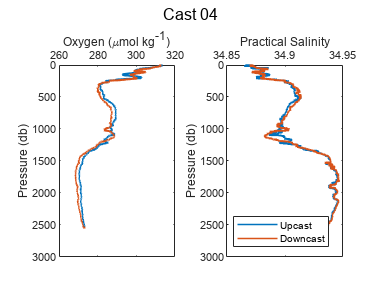

[cast04u, cast04d, btlsum04] = Process_Cast_Gain_E2_v2(cast04u,cast04d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 04');

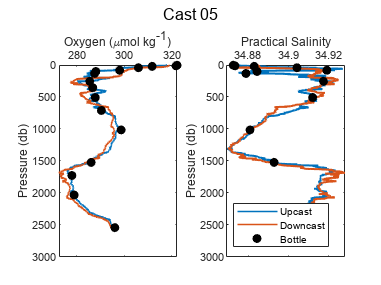

[cast05u, cast05d, btlsum05] = Process_Cast_Gain_E2_v2(cast05u,cast05d,cal,btlsum05,sal_plots,leah_plot,CTD_sen,'Cast 05');

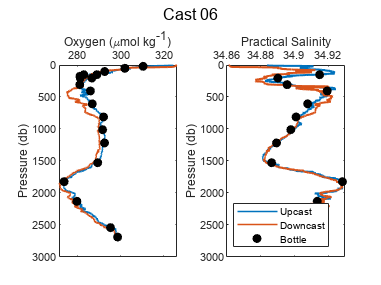

[cast06u, cast06d, btlsum06] = Process_Cast_Gain_E2_v2(cast06u,cast06d,cal,btlsum06,sal_plots,leah_plot,CTD_sen,'Cast 06');

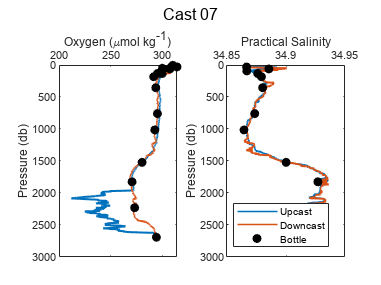

[cast07u, cast07d, btlsum07] = Process_Cast_Gain_E2_v2(cast07u,cast07d,cal,btlsum07,sal_plots,leah_plot,CTD_sen,'Cast 07');

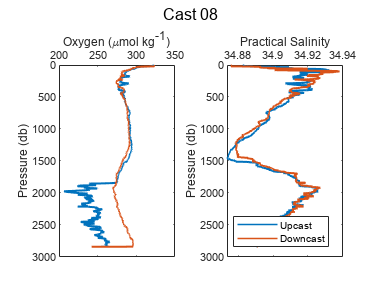

[cast08u, cast08d, btlsum08] = Process_Cast_Gain_E2_v2(cast08u,cast08d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 08');

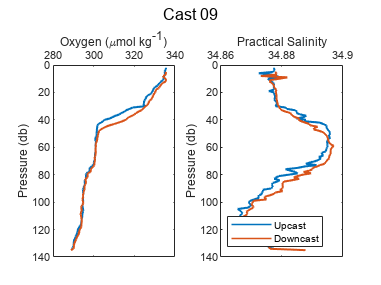

[cast09u, cast09d, btlsum09] = Process_Cast_Gain_E2_v2(cast09u,cast09d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 09');

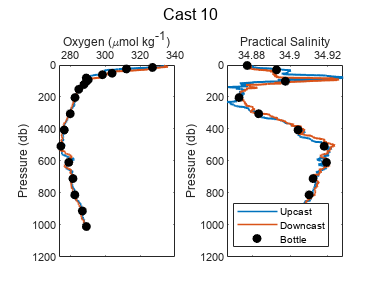

[cast10u, cast10d, btlsum10] = Process_Cast_Gain_E2_v2(cast10u,cast10d,cal10,btlsum10,sal_plots,leah_plot,CTD_sen,'Cast 10'); %% different cal10

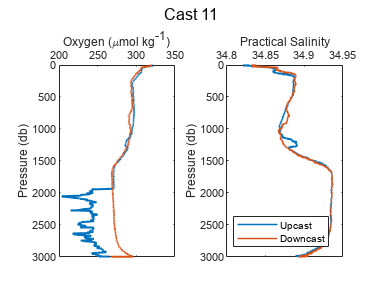

[cast11u, cast11d, btlsum11] = Process_Cast_Gain_E2_v2(cast11u,cast11d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 11');

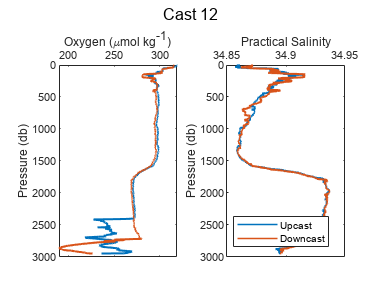

[cast12u, cast12d, btlsum12] = Process_Cast_Gain_E2_v2(cast12u,cast12d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 12');

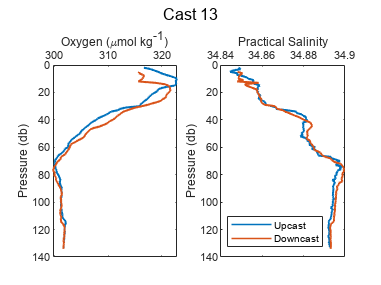

[cast13u, cast13d, btlsum13] = Process_Cast_Gain_E2_v2(cast13u,cast13d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 13');

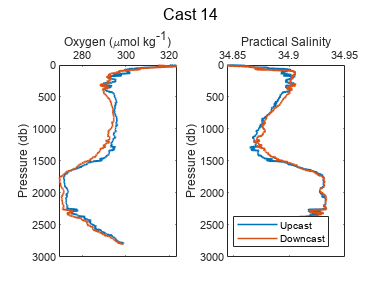

[cast14u, cast14d, btlsum14] = Process_Cast_Gain_E2_v2(cast14u,cast14d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 14');

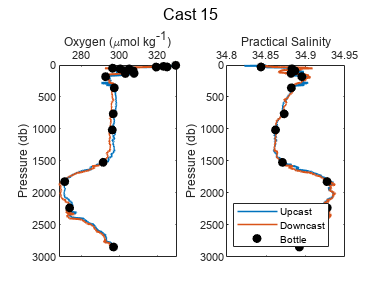

[cast15u, cast15d, btlsum15] = Process_Cast_Gain_E2_v2(cast15u,cast15d,cal,btlsum15,sal_plots,leah_plot,CTD_sen,'Cast 15');

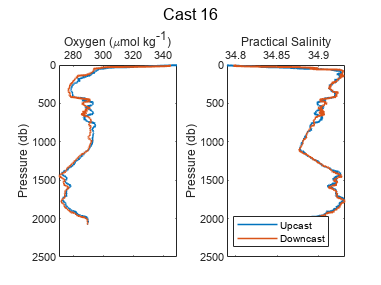

[cast16u, cast16d, btlsum16] = Process_Cast_Gain_E2_v2(cast16u,cast16d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 16');

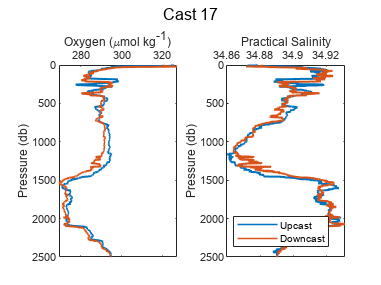

[cast17u, cast17d, btlsum17] = Process_Cast_Gain_E2_v2(cast17u,cast17d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 17');

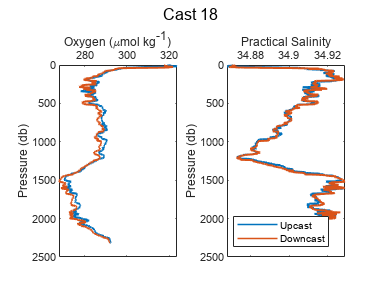

[cast18u, cast18d, btlsum18] = Process_Cast_Gain_E2_v2(cast18u,cast18d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 18');

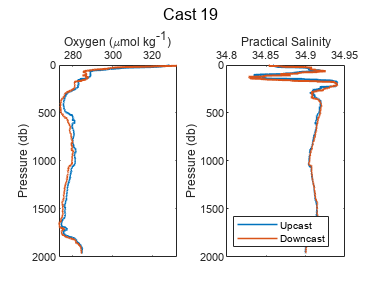

[cast19u, cast19d, btlsum19] = Process_Cast_Gain_E2_v2(cast19u,cast19d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 19');

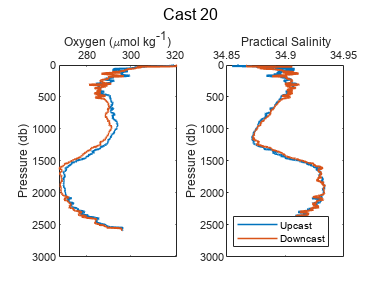

[cast20u, cast20d, btlsum20] = Process_Cast_Gain_E2_v2(cast20u,cast20d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 20');

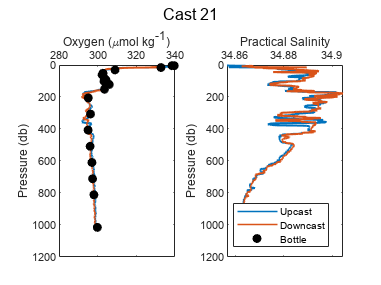

[cast21u, cast21d, btlsum21] = Process_Cast_Gain_E2_v2(cast21u,cast21d,cal21,btlsum21,sal_plots,leah_plot,CTD_sen,'Cast 21'); %% different cal21

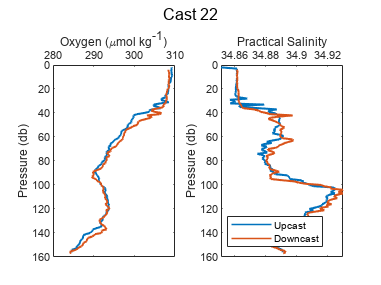

[cast22u, cast22d, btlsum22] = Process_Cast_Gain_E2_v2(cast22u,cast22d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 22');

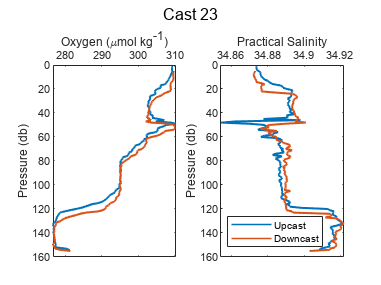

[cast23u, cast23d, btlsum23] = Process_Cast_Gain_E2_v2(cast23u,cast23d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 23');

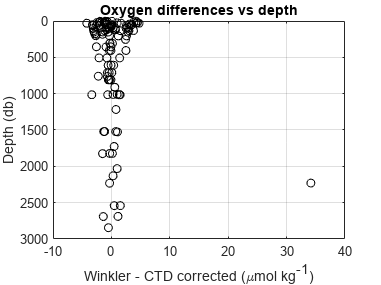

btlsum_yr5 = [btlsum05; btlsum06; btlsum07; btlsum10; btlsum15; btlsum21];
btlsum_yr5_OOI = btlsum_yr5; 

oxy_diff = btlsum_yr5.Winkler_umolkg-btlsum_yr5.DOcorr_umolkg;

figure
plot(oxy_diff,btlsum_yr5.prs,'ok')
axis ij
grid on
ylabel('Depth (db)')
xlabel('Winkler - CTD corrected (\mumol kg^-^1)')
title('Oxygen differences vs depth')


% nanmean(abs(oxy_diff(oxy_diff <10)))
% nanstd(abs(oxy_diff(oxy_diff <10)))



disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 4


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.0377


disp(['Adjust. E (cal10) term (E2) = ' num2str(cal10.E2)])

Adjust. E (cal10) term (E2) = 0.0359


disp(['Adjust. E (cal21) term (E2) = ' num2str(cal21.E2)])

Adjust. E (cal21) term (E2) = 0.0399


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.46146


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.47748


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.0347+/- 0.0076861



disp(['Cal 10 SOC = ' num2str(cal10.SOC)])

Cal 10 SOC = 0.46146


disp(['New Cal 10 SOC = ' num2str(cal10.SOCnew) ])

New Cal 10 SOC = 0.49074


disp(['Cal 10 E2Gain = ' num2str(cal10.E2gain) '+/- ' num2str(cal10.E2gainSTD)])

Cal 10 E2Gain = 1.0634+/- 0.0041457



disp(['Cal 21 SOC = ' num2str(cal21.SOC)])

Cal 21 SOC = 0.46146


disp(['New Cal 21 SOC = ' num2str(cal21.SOCnew) ])

New Cal 21 SOC = 0.48195


disp(['Cal 21 E2Gain = ' num2str(cal21.E2gain) '+/- ' num2str(cal21.E2gainSTD)])

Cal 21 E2Gain = 1.0444+/- 0.0044719


% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year5')
% clear btlsum0 btl 
% 
% dt_Processed = datetime;
% save Year5_Processed_KF cast* btl* cal* dt_Processed 


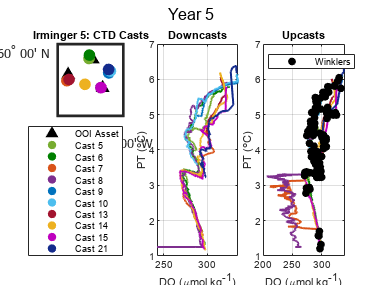

run('Year5_PT_DO_plots.m')